## DFT and windowing

*This lesson developed by request of the E80 profs!*

Section 1: Here is a signal with exactly three cycles of a sinusoid contained in N = 64 samples, sampled at 1 Hz. Note that the final point is n = 63 (this is N - 1. Starting at n = 0 gives a total of 64 samples). 

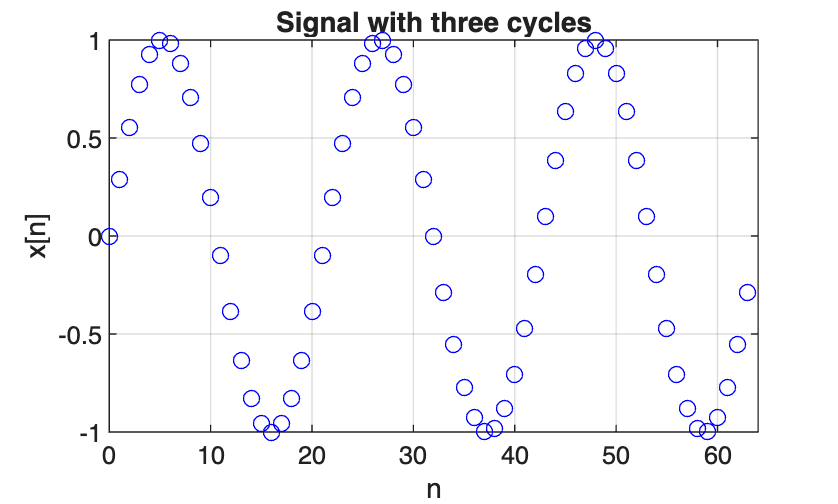

clear
N=64;
n =[0:N-1];  
x = 1*sin(2*pi*3/N*n); 
plot(n,x,'bo')  
xlabel('n')
ylabel('x[n]')
axis([0 64 -1 1])
title('Signal with three cycles')
grid on

Q: We are about to find the discrete Fourier transform (DFT) of this signal. The result will be X[k] values. How many of these will there be? How many will be non-zero? Explain your answer.

*ANS:   There will be 64 X[k] values, and two of them will be non-zero. I know this because 2 of the values have magnitudes of coefficients X[k] that aren't zero. *

The code below computes the DFT coefficients X[k] for this signal using the formula learned in class and makes a stem (spectrum) plot of the magnitude of X[k] vs k. Please look at the code and be sure you understand each line and then answer the questions below (nothing to edit in the code here).

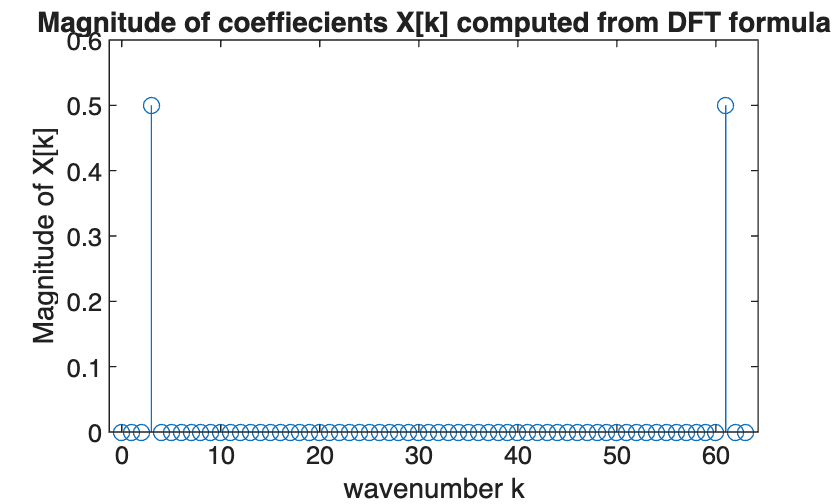

% Create a vector of DFT coefficients X[k]
for i=1:N
   k(i)=i-1; % Note: Matlab indexes vectors starting from 1
   X(i)=1/N*sum(x.*exp(-j*k(i)*2*pi*n/N));
end
stem(k,abs(X))  % we plot abs(X) to see magnitude (not showing phase info)
xlabel('wavenumber k')      
ylabel('Magnitude of X[k]')             
title('Magnitude of coeffiecients X[k] computed from DFT formula')

Q: Why are the magnitudes of the non-zero X[k] stems 0.5? 

ANS: Their magnitudes are 0.5 because 

Q: Explain why the non-zero X[k] stems occur at their specific wavenumber k locations. Use the relations in the box on slide 2 of the Day 08 notes.

ANS: The non-zero stems occur at the specific wavenumbers of k = 61 and k = 3 because the wavenumber of our signal is 

Now, instead of using the formula, compute the X[k] using Matlab's `fdomain.m`. Plot X[k] vs wavenumber k. ***Note that fdomain returns a vector of frequencies, not wavenumbers, so you will need to convert (the yellow highlighted boxes in the day08 notes will remind you how!)*

Fs = 1

Fs = 1

[X2,f2] = fdomain(x,Fs) % (uncomment and fill in code)

X2 =   -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.5000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.5000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i


f2 =    -0.5000   -0.4844   -0.4688   -0.4531   -0.4375   -0.4219   -0.4062   -0.3906   -0.3750   -0.3594   -0.3438   -0.3281   -0.3125   -0.2969   -0.2812   -0.2656   -0.2500   -0.2344   -0.2188   -0.2031   -0.1875   -0.1719   -0.1562   -0.1406   -0.1250   -0.1094   -0.0938   -0.0781   -0.0625   -0.0469   -0.0312   -0.0156         0    0.0156    0.0312    0.0469    0.0625    0.0781    0.0938    0.1094    0.1250    0.1406    0.1562    0.1719    0.1875    0.2031    0.2188    0.2344    0.2500    0.2656


To = N/Fs;
k = f2*To

k =    -32   -31   -30   -29   -28   -27   -26   -25   -24   -23   -22   -21   -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17


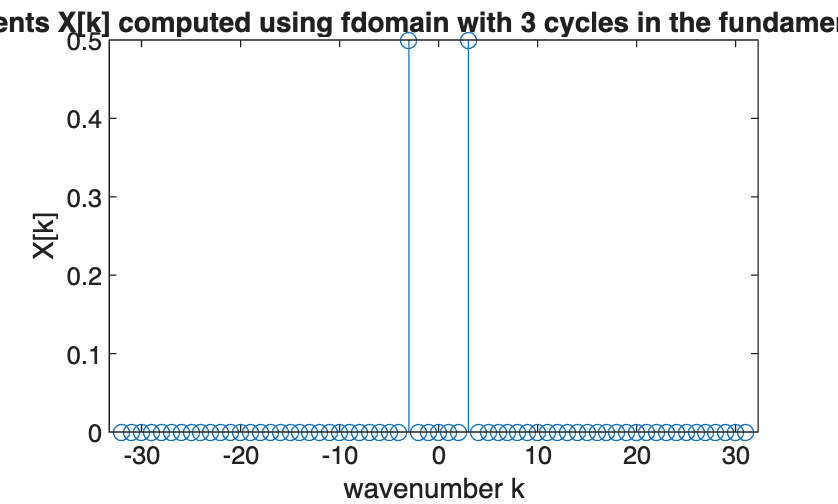


% Note you need to convert from frequency to wavenumber for the horizontal axis

 stem(k,abs(X2))
 xlabel('wavenumber k')
 ylabel('X[k]')
 title('Coefficients X[k] computed using fdomain with 3 cycles in the fundamental period')

This plot probably does not look like the first one above (stems at different locations). Before moving on, understand why they are different. *If you get to the end of this document before we bring the class together, you can work on editing the code above using the DFT formula to make it look like the plot produced using fdomain.*

Section 2: Now we'll create a signal that has 3.4 cycles within the 64 samples and plot the samples. Create the symmetric spectrum plot (magnitudes) for this signal, again with wavenumber on the horizontal axis. 

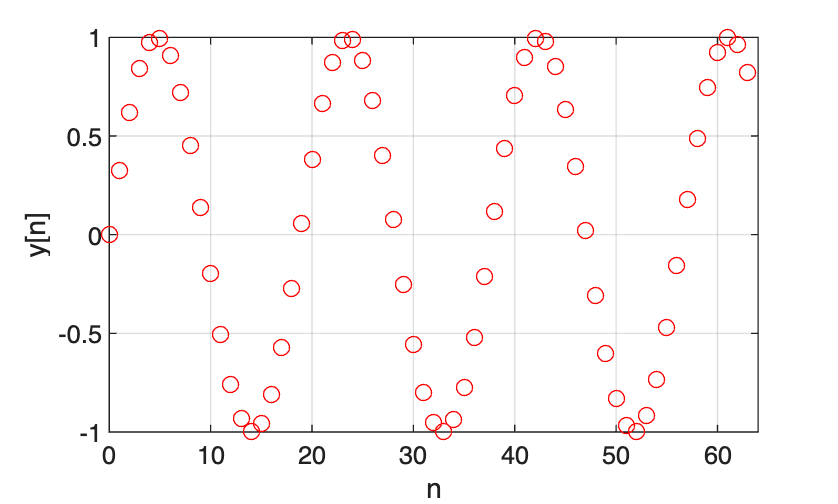

y = 1*sin(2*pi*3.4/N*n); 
plot(n,y,'ro'); 
xlabel('n')     
ylabel('y[n]')  
axis([0 64 -1 1])
grid on


% uncomment and complete these lines when ready to run this part
% [Y,f_Y] = fdomain...
% Note you need to convert from frequency to wavenumber for the horizontal axis
% k = ....
% stem(k,abs(Y),'r')
% xlabel('wavenumber k')
% ylabel('Y[k]')
% title('Coefficients Y[k] computed using fdomain with 3.4 cycles in the fundamental period')

Discuss why this looks significantly different from the spectrum plot above.

*ANS: *

Section 3: The "leakage" into the other DFT coefficients is unavoidable in analysis of real-world, finite length discrete signals. A strategy for dealing with this is called **windowing**, where we multiply the signal by a function in the time domain that reduces undesired behavior in the frequency domain. In particular here we will examine the **Hanning window. **

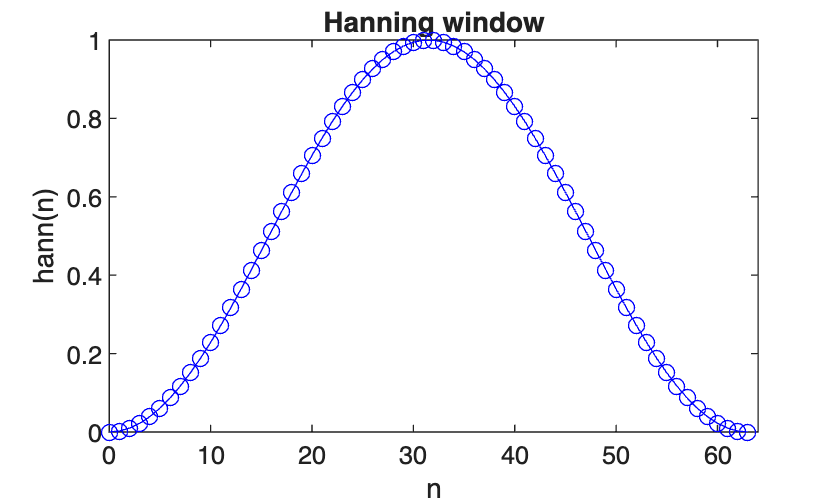

h=hann(N);  
plot(n,h,'bo-');
xlabel('n')
ylabel('hann(n)')
title('Hanning window')
axis([0 64 0 1])

Multiply the signal y[n] by the Hanning window function to get the modified signal y_windowed[n]. Plot the *windowed* signal in the time domain. Then plot the spectrum of the DFT of y[n] and of the windowed version y_windowed[n] together on the same figure and comment on the differences in amplitude and width (leakage). 

% uncomment when ready to run this part
% y_windowed = ... (uncomment and fill in code)
% plot(n,y_windowed,'ko')
% axis([0 64 -1 1])
% xlabel('n')
% ylabel('windowed y[n]')
%title('Signal with 3.4 cycles with Hanning window')

% stem(k,abs(Y),'r')
% Y_windowed = fdomain... (fill in code)
% hold on
% stem(k,abs(Y_windowed),'k')
% xlabel('wavenumber k')
% ylabel('Y[k]')
% legend('original signal','windowed signal fdomain')
% title({'Original and windowed signal','with 3.4 cycles in the fundamental period'})
% hold off


If you get to this point early, do one or both of these things. 

- Go back to your first stem plot in Section 1 and figure out how to rearrange the wavenumbers to make your result look like the one produced in the next plot by fdomain.

- At the end of class Prof. Yong will show an example of a **spectrogram.** Examine the examples in the documentation for the Matlab `spectrogram` and try to understand what that kind of plot shows.